hold on
grid on 
ylim([0,140])
xlim ([0,140])
x = [11 30 40 41 50 70 81 90 120 131];
y = [22 23 32 50 40 55 83 72 96 122];
point = scatter(x, y, 'blue');
x_1 = [11 41 81 131];
y_1 = [22 50, 83 122];
x_2 = [30 40 50 70 90 120];
y_2 = [23 32 40 55 72 96];
coeff_1 = polyfit(x_1,y_1, 1)

coeff_1 =     0.8290   14.5352


y1 = 0;
xi = min(0):0.1:max(140)

xi =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


for k=0:1
    y1 = y1 + coeff_1(1-k+1) * xi.^k;
end
gr_1 = plot(xi, y1,'blue'); 
coeff_2 = polyfit(x_2,y_2, 1)

coeff_2 =     0.8058   -0.7209


y1 = 0;
xi = min(0):0.1:max(140)

xi =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


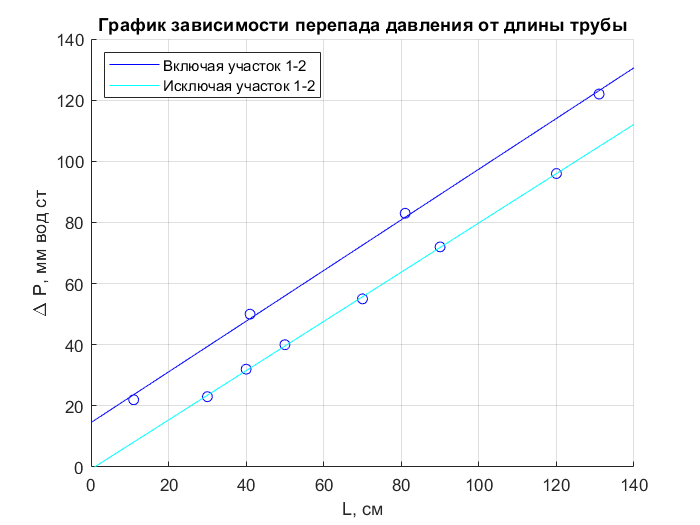

for k=0:1
    y1 = y1 + coeff_2(1-k+1) * xi.^k;
end
gr_2 = plot(xi, y1,'cyan'); 
title("График зависимости перепада давления от длины трубы")
xlabel('L, см')
ylabel('\Delta P, мм вод ст')
legend([gr_1, gr_2], {'Включая участок 1-2', "Исключая участок 1-2"}, 'Location','northwest')
hold off